### 6) Referring to Problem B–8–4, obtain the response of the PID-controlled system shown in Figure 8–73(a) to the unit-step disturbance input. Show that for the disturbance input, the responses of the PID-controlled system shown in Figure 8–73(a) and of the IPD-controlled system shown in Figure 8–73(b) are exactly the same. [When considering D(s) to be the input, assume that the reference input R(s) is zero, and vice versa.] Also, compare the closed-loop transfer function C(s)/R(s) of both systems.

## **1 ) Respuesta de un sistema con controlador PID a una entrada de perturbación escalón con referencia nula.**

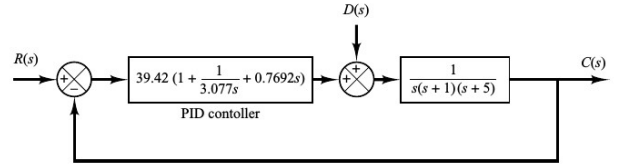

La función de transferencia del sistema frente a la perturbación viene dada por:


$$\frac{C\left(s\right)}{D\left(s\right)}=\frac{\mathrm{Gp}\left(s\right)}{1+\mathrm{Gc}\left(s\right)\mathrm{Gp}\left(s\right)}$$


En este caso:


$$\textrm{Gc}\left(s\right)=39\ldotp 42\left(1+\frac{1}{3\ldotp 077s}+0\ldotp 7692s\right)=\frac{30\ldotp 32s^2 +39\ldotp 42s+12\ldotp 81}{s}$$



$$\textrm{Gp}\left(s\right)=\frac{1}{s\left(s+1\right)\left(s+5\right)}=\frac{1}{s^3 +6s^2 +5s}$$


Gc = tf([30.32 39.42 12.81],[1 0]);
Gp = tf([0 1],[1 6 5 0]);
G1 = Gp/(1+Gc*Gp) 

G1 =
 
                          s^4 + 6 s^3 + 5 s^2
  --------------------------------------------------------------------
  s^7 + 12 s^6 + 76.32 s^5 + 281.3 s^4 + 425.9 s^3 + 274 s^2 + 64.05 s
 
Continuous-time transfer function.



t=0:0.01:20; % Tiempo.
h1 = stepplot(G1) % Respuesta con entrada de perturbación escalón unitario con referencia nula.


h1 =

	resppack.timeplot



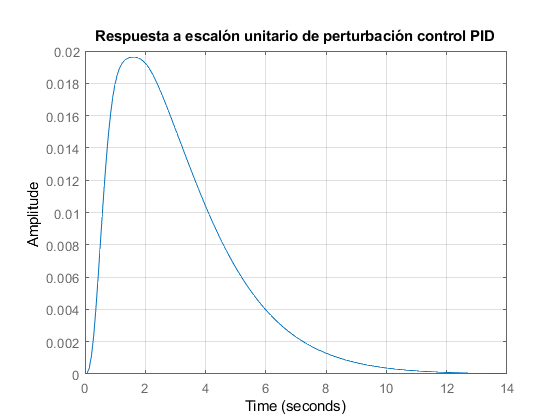

setoptions(h1,'Grid','on');
title('Respuesta a escalón unitario de perturbación control PID')

## 2)  **Respuesta de un sistema con controlador I-PD a una entrada de perturbación escalón con referencia nula.**

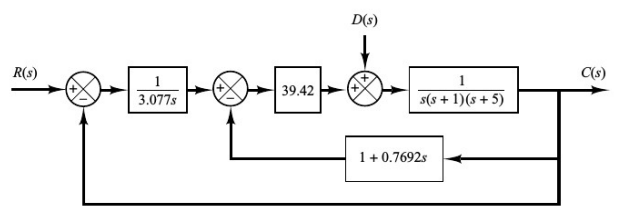

La función de transferencia del sistema frente a la perturbación viene dada por::


$$\frac{C\left(s\right)}{D\left(s\right)}=\frac{\mathrm{Gp}\left(s\right)}{1+\mathrm{Gp}\left(s\right)\mathrm{g2}\left(s\right)\left\lbrack \mathrm{g1}\left(s\right)+\mathrm{h1}\left(s\right)\right\rbrack }$$


Donde:


$$\textrm{h1}\left(s\right)=1+0\ldotp 7692s$$



$$\mathrm{g2}\left(s\right)=39\ldotp 42$$



$$\textrm{g1}\left(s\right)=\frac{1}{3\ldotp 077s}\;$$


g1 = tf([0 1],[3.077 0]);
g2 = tf([0 39.42],[0 1]);
Gp = tf([0 1],[1 6 5 0]);
h1 = tf([0.7692 1],[0 1]); 
G2 = Gp/(1+Gp*g2*(g1+h1))

G2 =
 
                       3.077 s^4 + 18.46 s^3 + 15.38 s^2
  ----------------------------------------------------------------------------
  3.077 s^7 + 36.92 s^6 + 234.8 s^5 + 865.7 s^4 + 1311 s^3 + 843 s^2 + 197.1 s
 
Continuous-time transfer function.



h2 = stepplot(G2) % Respuesta con entrada de perturbación escalón unitario con referencia nula.


h2 =

	resppack.timeplot



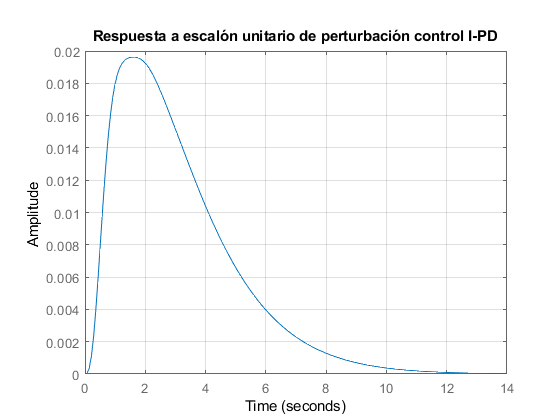

setoptions(h2,'Grid','on');
title('Respuesta a escalón unitario de perturbación control I-PD')

Se observa que ambas funciones de transferencia de lazo cerrado frente a perturbaciones con referencia nula son identicas, por ende sus respuestas también lo son. 

En ausencia de la entrada de referencia y de ruido, la función de transferencia en lazo cerrado entre la perturbación D(s) y la salida C(s) es igual en cualquier caso para las mismas constantes.